%---------------------------------------------------------------------------
%
%	Hoo CONTROL LAUNCHER
%	TD
%	M.SAUZAY (ASTRIUM ST) - 2013
%
%---------------------------------------------------------------------------
% This file gathers all the MATLAB command to run in order to anwser to the
% practice exercice
%---------------------------------------------------------------------------
% Script:
% - TD_Hoo_Control_Flexible_Launcher_student.m
% - plot_rigid_launcher_simu.m
% - plot_flexible_launcher_simu.m
% - rigid_launcher_OL.mdl
% - rigid_launcher_CL.mdl
% - flexible_launcher_CL.mdl
% - flexible_launcher_syn.mdl

%---------------------------------------------------------------------------
% 	Rigid launcher numerical data
%---------------------------------------------------------------------------

A1     =    -31.6;
A2     =     -0.0467;
A3     =      0.005;
A6     =      1.631;
xi0    =      0.63;
omega0 =     23.9;
B1     =     -0.005;
B2     =      0.0467;
K1     =     -2.514;
K2     =    -15.6893;
Vr     =    325.34;
xiq    =      0.005;
omegaq =     23.88;
Aq     = -10572;
dhdx   =     -5.46*10^(-4);
t0     = [0 4.5 23.71 26.81 40.50 44.01 44.11 44.90 45.00 126.68];
deltaW = [0 0 -12.5 -10.5 7 18 27.9 28.3 18.6 50.1];


%---------------------------------------------------------------------------
% 	2- Launcher models
%---------------------------------------------------------------------------

% 2.1 - Time domain simulation (rigid launcher)
% -----------------------------------------------------------
% Open loop rigid launcher model
% State vector    : x^T = (Theta',Theta,z',beta_R',beta_R)
% Input vector  : u^T = (beta_c,W,beta_FZ)
% Output vector : y^T = (x^T,alpha)

Ar = [0 A6 A3             0        K1;
      1  0  0             0         0;
      0 A1 A2             0        K2;
      0  0  0 -2*xi0*omega0 -omega0^2;
      0  0  0             1         0];

Br = [0        B1 K1;
      0         0  0;
      0        B2 K2;
      omega0^2  0  0;
      0         0  0];

% Q1: to be completed
Calpha = [0 1 1/Vr 0 0];
Dalpha = [0 -1/Vr 0];

Cr = [eye(5,5);
        Calpha];

Dr = [zeros(5,3);
    Dalpha];

% linear model (file "rigid_launcher_OL" is given)
[arbo,brbo,crbo,drbo] = linmodv5('rigid_launcher_OL');
valrbo = eig(arbo)

valrbo =    0.0000 + 0.0000i
  -1.3246 + 0.0000i
   1.2276 + 0.0000i
   0.0503 + 0.0000i
 -15.0570 +18.5606i
 -15.0570 -18.5606i



% Q2: Time domain simulation: Input = deflection step (magnitude = 1° during 1s)  
t  = [0:0.1:4]';
nt = max(size(t));
ut = ones(nt,1);

betac1 = 1*pi/180;
betac2 = 0;
vent   = 0;
betafz = 0;

u = [t,[betac1*ut(1:11); betac2*ut(12:nt)],vent*ut,betafz*ut];

[tt,x,y] = sim('rigid_launcher_OL',[0 max(t)],[],u);

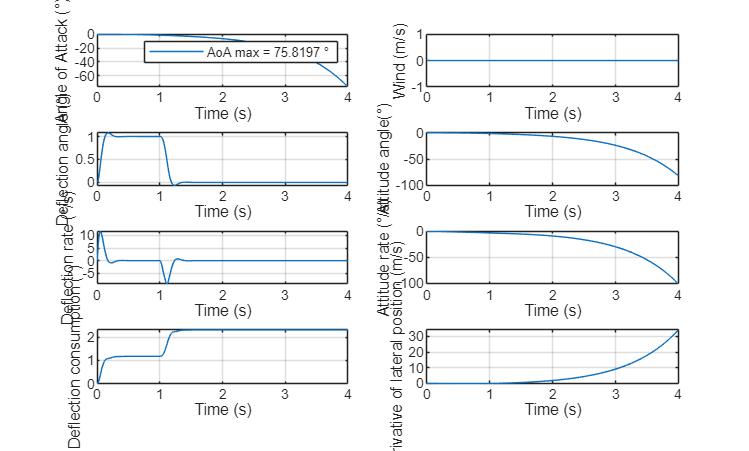


% Q3: "plot_rigid_launcher_simu" is a script (reused for each simulation), 
% that gathers on the same figure:
% Angle of attack, wind, deflection rate,  deflection angle, deflection
% integral, attitude rate, attitude angle, derivate of lateral position
% error.

plot_rigid_launcher_simu



% 2.2 - Synthesis model
% -----------------------------------------------------------
% Rigid launcher model for synthesis
% State vector    : x^T = (Theta',Theta,z',beta_R',beta_R)
% Input vector  : u^T = (beta_c)
% Output vector : y^T = (Theta)


% Q4: linear model (model "rigid_launcher_syn" has to be built from
% "rigid_launcher_OL")
[asynbo,bsynbo,csynbo,dsynbo] = linmodv5('rigid_launcher_syn');
valsynbo = eig(asynbo)

valsynbo =   -1.3246 + 0.0000i
   1.2276 + 0.0000i
   0.0503 + 0.0000i
 -15.0570 +18.5606i
 -15.0570 -18.5606i


damp(asynbo)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.32e+00                 1.00e+00       1.32e+00          7.55e-01    
  1.23e+00                -1.00e+00       1.23e+00         -8.15e-01    
  5.03e-02                -1.00e+00       5.03e-02         -1.99e+01    
 -1.51e+01 + 1.86e+01i     6.30e-01       2.39e+01          6.64e-02    
 -1.51e+01 - 1.86e+01i     6.30e-01       2.39e+01          6.64e-02    



% Q5: Bode plot / eigenvalues
sys_syn = ss(asynbo,bsynbo,csynbo,dsynbo);
tf(sys_syn)


ans =
 
                      -1436 s - 111.9
  -------------------------------------------------------
  s^5 + 30.16 s^4 + 571 s^3 - 22.36 s^2 - 929.2 s + 46.74
 
Continuous-time transfer function.


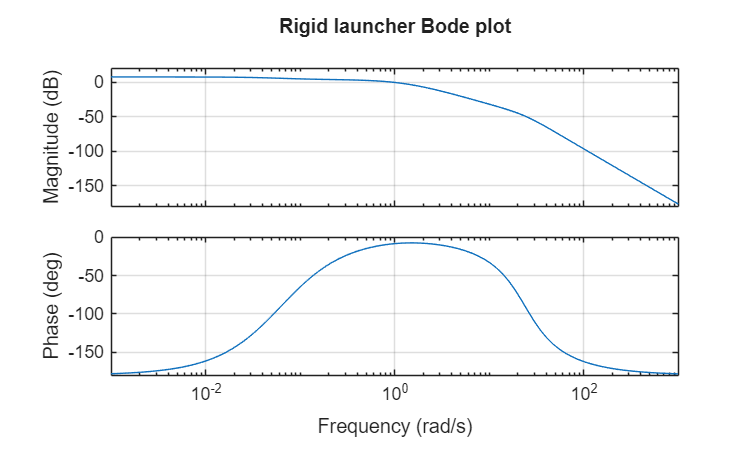


figure; set(gcf,'color','white'); clf; 
bode(sys_syn)
grid
title('Rigid launcher Bode plot')

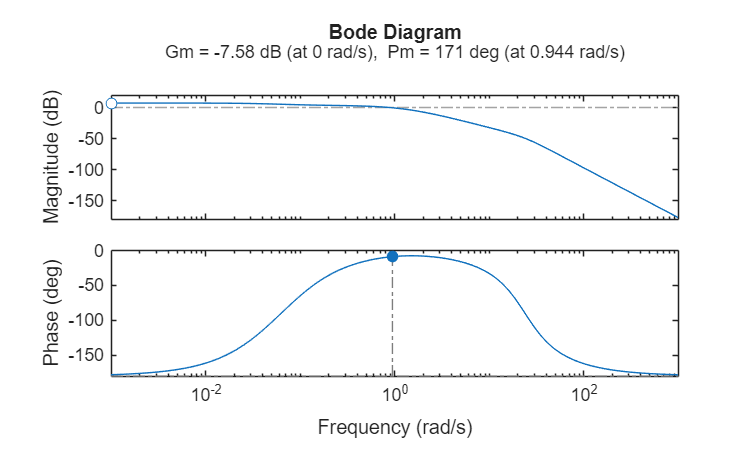

margin(sys_syn)


%---------------------------------------------------------------------------
% 	3 - Augmented system
%---------------------------------------------------------------------------

% 3.1 - Weigthing functions
% -------------------------

% Initial data
k1 = 0.33;
a1 = 3.14;
b1 = 0.0628;
k2 = 0.08;
a2 = 22;
b2 = 22;
k3 = 0.7;

% W1
numW1 = k1*[1 a1];
denW1 = [1 b1];
sysW1 = tf(numW1,denW1);
ss(sysW1);

% W2
numW2    = k2*[1 a2];
denW2    = [1 b2];
sysW2    = tf(numW2,denW2);
ss(sysW2);

% W3
numW3 = k3;
denW3 = 1;
sysW3 = tf(numW3,denW3);
ss(sysW3);

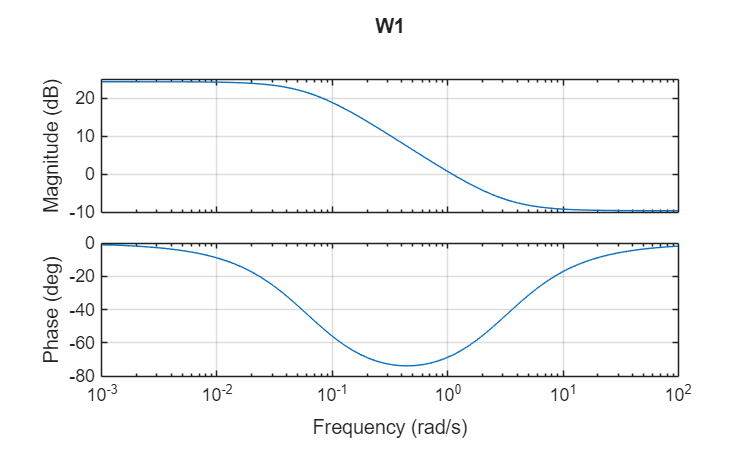


% Q6: Weigthing functions Bode plots
figure
bode(sysW1)
grid
title('W1')

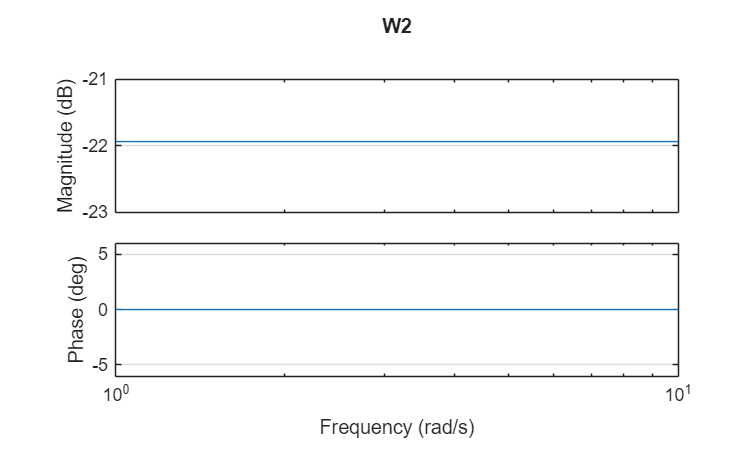


% to be completed
figure
bode(sysW2)
grid
title('W2')

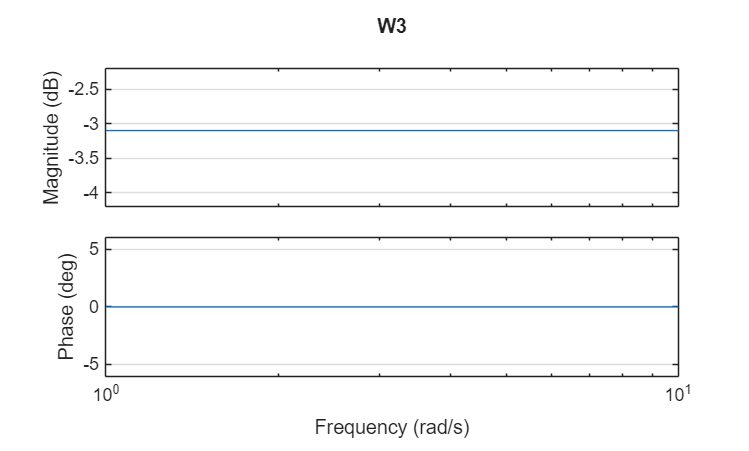


figure
bode(sysW3)
grid
title('W3')

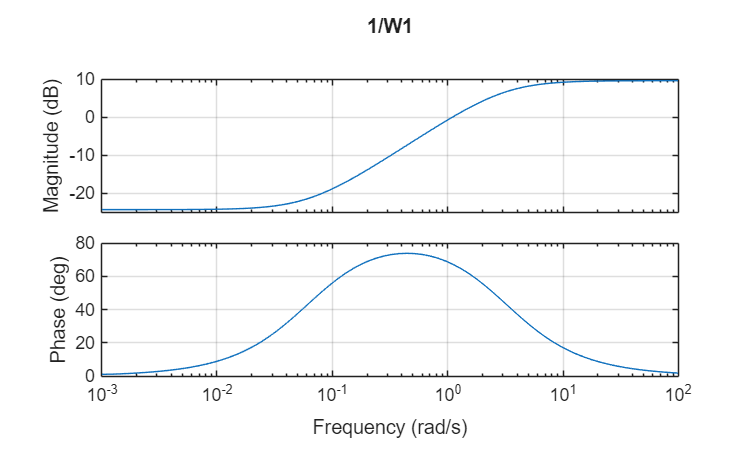


% Q7 : Inverse weighting functions Bode plots
figure
bode(1/sysW1)
grid
title('1/W1')

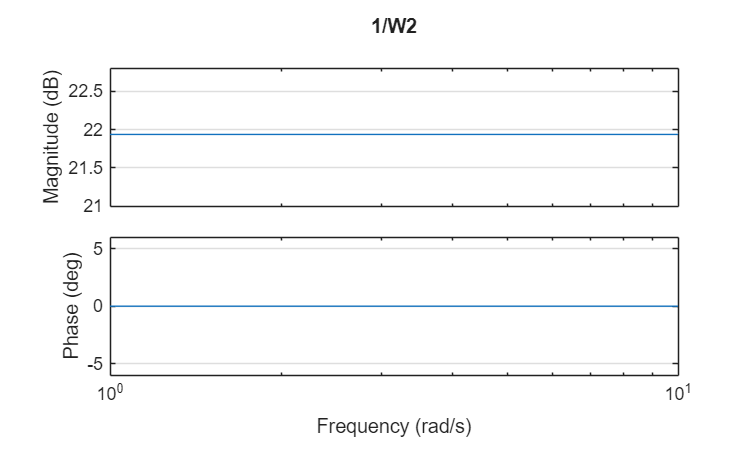


% to be completed
figure
bode(1/sysW2)
grid
title('1/W2')

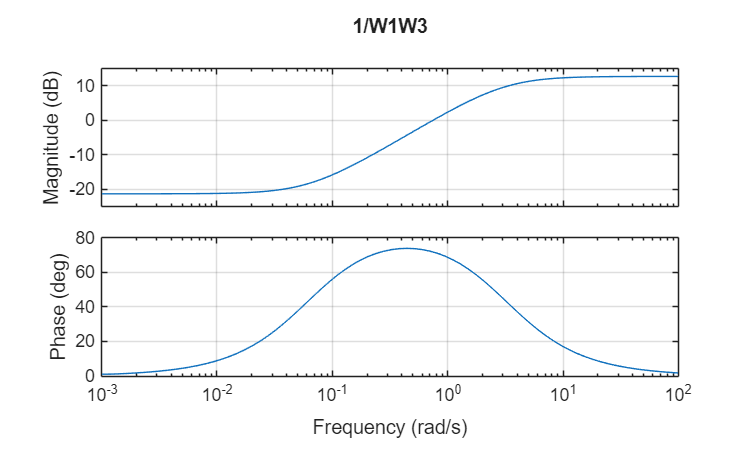


figure
bode(1/(sysW1*sysW3))
grid
title('1/W1W3')

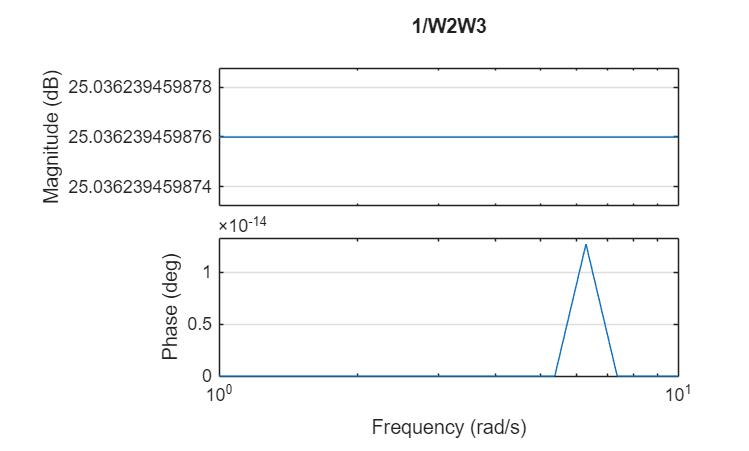


figure
bode(1/(sysW2*sysW3))
grid
title('1/W2W3')


% 3.2 - Augmented model
% ---------------------
% Q8: Augmented model for Hinf synthesis
% State vector    : x^T = (Theta',Theta,z',beta_R',beta_R)
% Input vector (disturbancee)               : w^T = (w1,w2)
% Output vector (Outputs to be controlled)  : z^T = (z1,z2)
% Command                                   : u^T = (beta_c)
% Measurement                               : y^T = (e)

% file "augmented_model" has to be built from the Figure 2


%---------------------------------------------------------------------------
% 	4 - First Hinf controller synthesis and assessment
%---------------------------------------------------------------------------
% 4.1 - Hinf controller synthesis
% ---------------------------------------------------
% Linear model
[asyn,bsyn,csyn,dsyn] = linmodv5('augmented_model');
valsyn = eig(asyn)

valsyn =   -0.0628 + 0.0000i
  -1.3246 + 0.0000i
   1.2276 + 0.0000i
   0.0503 + 0.0000i
 -15.0570 +18.5606i
 -15.0570 -18.5606i
 -22.0000 + 0.0000i



% Q9: Hinf controller synthesis using hinfsyn matlab command
% [K,Gbf,gfin] = ...
%     hinfsyn(syspack,nmeas,ncontr,gamma_min,gamma_max,tol,method)
% see Matlab help for more details
% Assumption:  inputs/outputs of the augmented model are ordered to have in
% last position the controller command and the measurement

syspack = pck(asyn,bsyn,csyn,dsyn);
[k,Gbf,gfin] = hinfsyn(syspack,1,1,0,1000,1e-1,1);

Resetting value of Gamma min based on D_11, D_12, D_21 terms

Test bounds:      0.3300 <  gamma  <=   1000.0000

  gamma    hamx_eig  xinf_eig  hamy_eig   yinf_eig   nrho_xy   p/f
1.000e+03   7.8e-02   0.0e+00   6.3e-02   -4.4e-16    0.0000    p 
  500.165   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0000    p 
  250.248   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0000    p 
  125.289   7.8e-02   0.0e+00   6.3e-02   -6.7e-17    0.0001    p 
   62.809   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0002    p 
   31.570   7.8e-02   0.0e+00   6.3e-02   -4.2e-18    0.0009    p 
   15.950   7.8e-02   0.0e+00   6.3e-02   -1.4e-18    0.0034    p 
    8.140   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0133    p 
    4.235   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0495    p 
    2.282   7.8e-02   0.0e+00   6.3e-02   -2.1e-19    0.1771    p 
    1.306   7.8e-02   0.0e+00   6.3e-02   -2.4e-19    0.6115    p 
    0.818   7.8e-02   0.0e+00   6.3e-02    0.0e+00    2.3169#   f 
    1.166   7.8e

[ak,bk,ck,dk] = unpck(k);
% eigenvalues of the controlled launcher
[agbf,bgbf,cgbf,dgbf] = unpck(Gbf);
valgbf = eig(agbf)

valgbf = 1.0e+02 *

  -0.0006 + 0.0000i
  -0.2200 + 0.0000i
  -0.2200 + 0.0000i
  -1.2558 + 0.0000i
  -0.1506 + 0.1856i
  -0.1506 - 0.1856i
  -0.1494 + 0.1859i
  -0.1494 - 0.1859i
  -0.0283 + 0.0135i
  -0.0283 - 0.0135i
  -0.0142 + 0.0062i
  -0.0142 - 0.0062i
  -0.0007 + 0.0000i
  -0.0008 + 0.0000i



% Q10: The controller K
valk = eig(ak)

valk = 1.0e+02 *

  -0.2200 + 0.0000i
  -1.2557 + 0.0000i
  -0.1387 + 0.1906i
  -0.1387 - 0.1906i
  -0.1060 + 0.0000i
  -0.0008 + 0.0000i
  -0.0006 + 0.0000i


K = ss(ak,bk,ck,dk);
damp(K)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.28e-02                 1.00e+00       6.28e-02         1.59e+01    
 -7.80e-02                 1.00e+00       7.80e-02         1.28e+01    
 -1.06e+01                 1.00e+00       1.06e+01         9.43e-02    
 -2.20e+01                 1.00e+00       2.20e+01         4.55e-02    
 -1.39e+01 + 1.91e+01i     5.88e-01       2.36e+01         7.21e-02    
 -1.39e+01 - 1.91e+01i     5.88e-01       2.36e+01         7.21e-02    
 -1.26e+02                 1.00e+00       1.26e+02         7.96e-03    


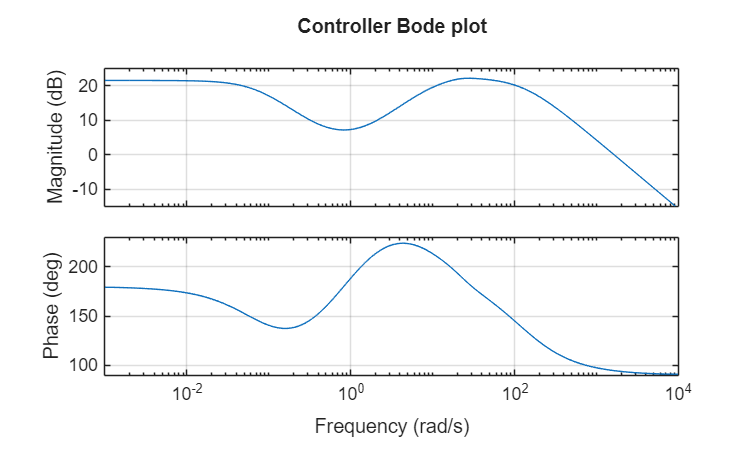

figure
bode(K)
grid
title('Controller Bode plot')

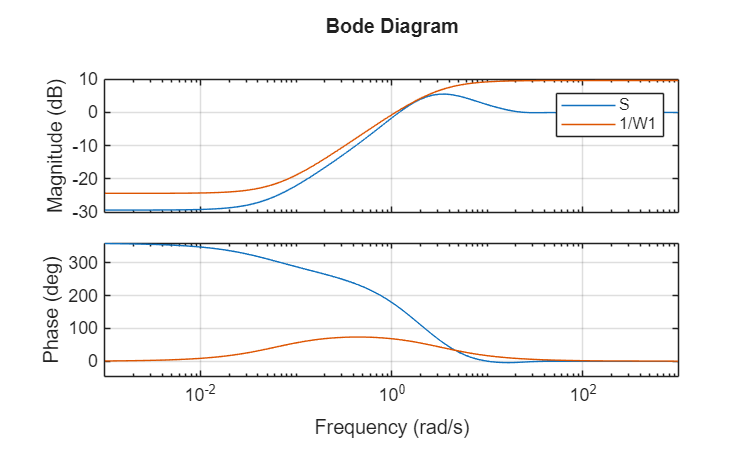


% Q10: Comparison between the augmented system transfer functions and the
% weighting functions
S  = 1/(1+K*sys_syn);
GS = sys_syn/(1+K*sys_syn);
KS = K/(1+K*sys_syn);
T  = K*sys_syn/(1+K*sys_syn);

figure
bode(S,1/sysW1)
legend('S','1/W1')
grid

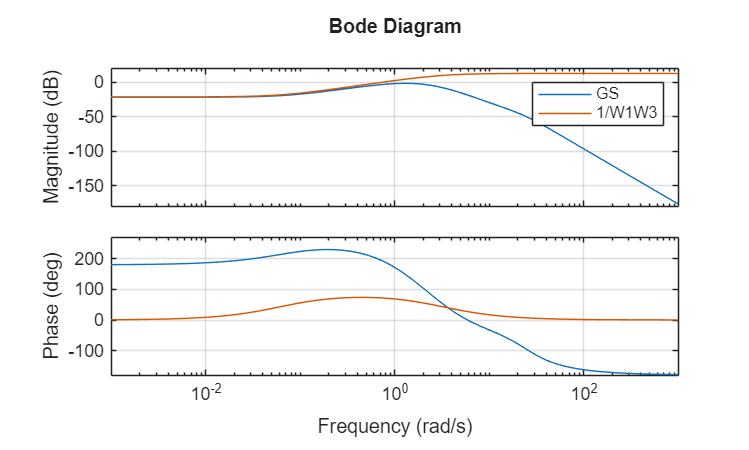


figure
bode(GS,1/(sysW1*sysW3))
legend('GS','1/W1W3')
grid

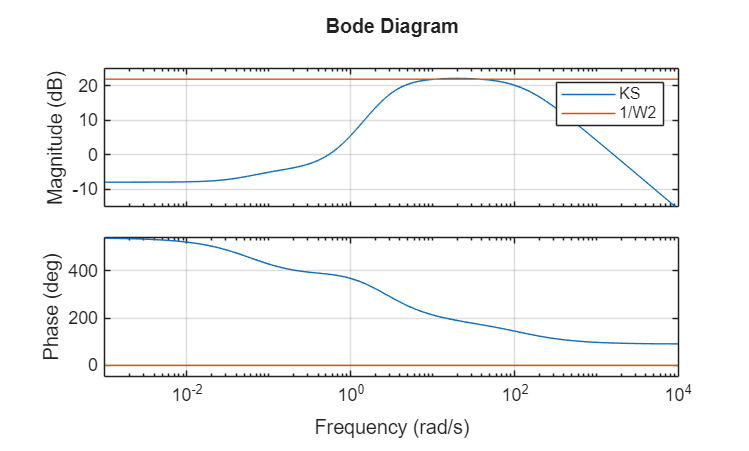


figure
bode(KS,1/sysW2)
legend('KS','1/W2')
grid

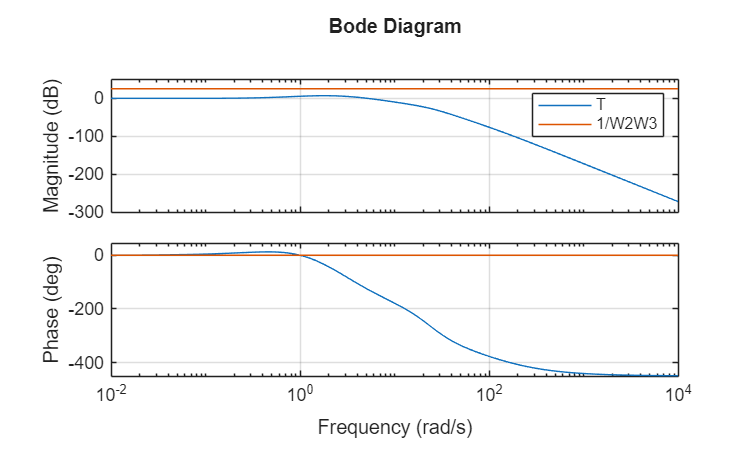


figure
bode(T,1/(sysW2*sysW3))
legend('T','1/W2W3')
grid

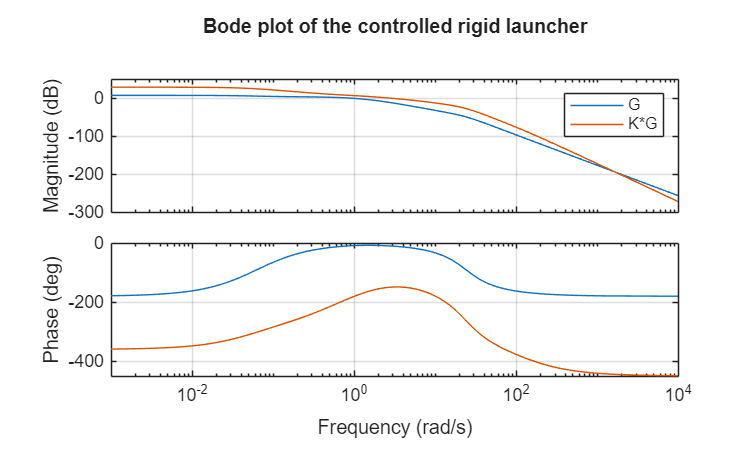


% 4.2 - Frequency domain assessment (rigid launcher)
% --------------------------------------------------

% Q11: Bode plot of the controlled rigid launcher
figure
bode(sys_syn,K*sys_syn)

legend('G','K*G')
grid
title('Bode plot of the controlled rigid launcher')

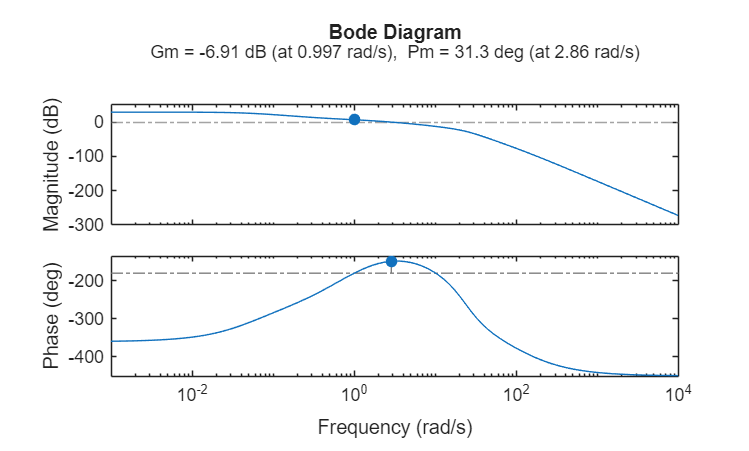

margin(K*sys_syn)

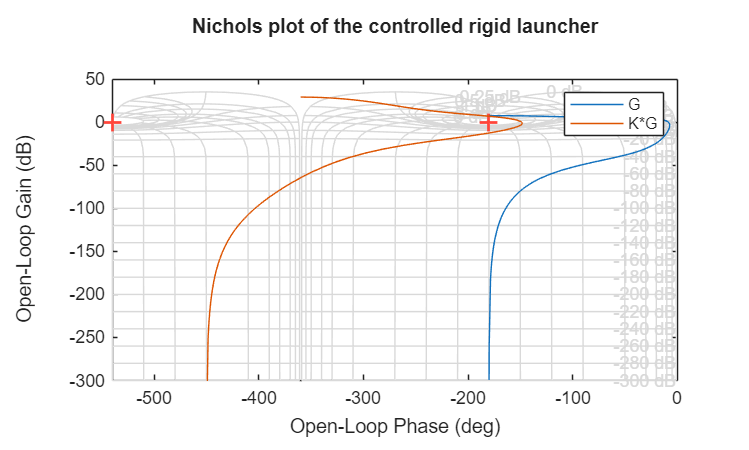


% Q11, Q12, Q13: Nichols plot of the controlled rigid launcher
figure
nichols(sys_syn,K*sys_syn)
legend('G','K*G')
grid
title('Nichols plot of the controlled rigid launcher')

allmargin(K*sys_syn)

ans = struct with fields:
     GainMargin: [0.4514 4.2585]
    GMFrequency: [0.9972 10.1151]
    PhaseMargin: 31.2671
    PMFrequency: 2.8631
    DelayMargin: 0.1906
    DMFrequency: 2.8631
         Stable: 1



% poles of the closed-loop system
[Zeros,Poles,gain]=zpkdata(feedback(K,sys_syn),'v')

Zeros =  -15.0570 +18.5606i
 -15.0570 -18.5606i
 -15.0570 +18.5606i
 -15.0570 -18.5606i
  -1.2674 + 0.0000i
  -0.5413 + 0.0000i
  -0.0671 + 0.0000i
  -1.3246 + 0.0000i
   1.2276 + 0.0000i
   0.0503 + 0.0000i


Poles = 1.0e+02 *

  -1.2558 + 0.0000i
  -0.1494 + 0.1859i
  -0.1494 - 0.1859i
  -0.1506 + 0.1856i
  -0.1506 - 0.1856i
  -0.0283 + 0.0135i
  -0.0283 - 0.0135i
  -0.0142 + 0.0062i
  -0.0142 - 0.0062i
  -0.0007 + 0.0000i
  -0.0008 + 0.0000i


gain = -1.6383e+03

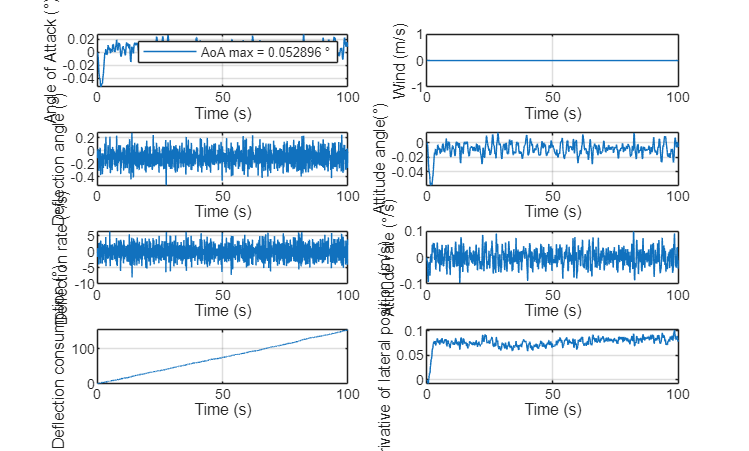


% 4.3 - Time domain simulation (rigid launcher)
% ---------------------------------------------

% model "rigid_launcher_CL.mdl" is given

% Q14: case 1: zero guidance input, no wind, constant thrust deflection offset
% 0.1deg
t  = [0:0.1:100]';
nt = max(size(t));

thetac     = 0;
ventonoff = 0;
betafz    = 0.1*3.14/180;

[tt,x,y] = sim('rigid_launcher_CL',[0 max(t)]);

plot_rigid_launcher_simu


% Q14: case 2: zero guidance input, wind profile, no thrust deflection offset
t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 1/58 %1 degree;

thetac = 0.0172

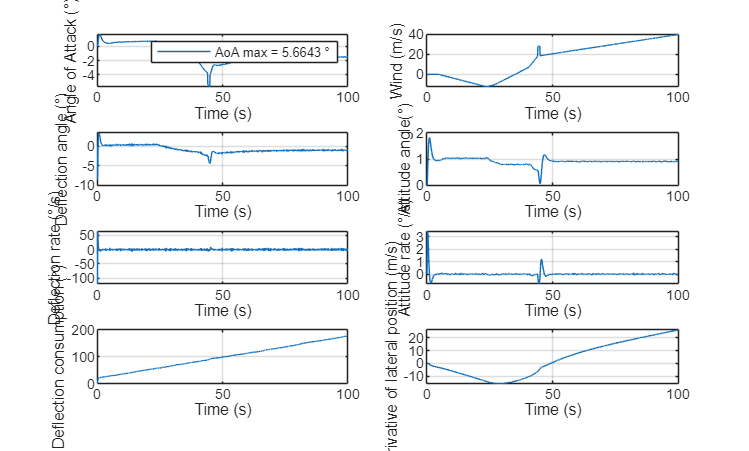

ventonoff = 1;
betafz    = 0;

[tt,x,y] = sim('rigid_launcher_CL',[0 max(t)]);

plot_rigid_launcher_simu


%---------------------------------------------------------------------------
% 	5 - Controller settings
%---------------------------------------------------------------------------
% 5.1 - Sensitivity study (Q15, Q16, Q17)
% ----------------------

% Q15: 
% Initial data
k1 = 0.33;
a1 = 3.14;
b1 = 0.0628;
k2 = 0.08;
a2 = 22;
b2 = 22;
k3 = 0.7;

%Valeur Modifié :

numW2    = k2*[1 a2];
denW2    = [1 b2];
sysW2    = tf(numW2,denW2);

numW3  = k3;
denW3    = 1;
sysW3    = tf(numW3,denW3);


% Hinifinity synhtesis
[asyn,bsyn,csyn,dsyn] = linmodv5('augmented_model');
syspack      = pck(asyn,bsyn,csyn,dsyn);
[k,Gbf,gfin] = hinfsyn(syspack,1,1,0,1000,1e-1,1);

Resetting value of Gamma min based on D_11, D_12, D_21 terms

Test bounds:      0.3300 <  gamma  <=   1000.0000

  gamma    hamx_eig  xinf_eig  hamy_eig   yinf_eig   nrho_xy   p/f
1.000e+03   7.8e-02   0.0e+00   6.3e-02   -4.4e-16    0.0000    p 
  500.165   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0000    p 
  250.248   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0000    p 
  125.289   7.8e-02   0.0e+00   6.3e-02   -6.7e-17    0.0001    p 
   62.809   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0002    p 
   31.570   7.8e-02   0.0e+00   6.3e-02   -4.2e-18    0.0009    p 
   15.950   7.8e-02   0.0e+00   6.3e-02   -1.4e-18    0.0034    p 
    8.140   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0133    p 
    4.235   7.8e-02   0.0e+00   6.3e-02    0.0e+00    0.0495    p 
    2.282   7.8e-02   0.0e+00   6.3e-02   -2.1e-19    0.1771    p 
    1.306   7.8e-02   0.0e+00   6.3e-02   -2.4e-19    0.6115    p 
    0.818   7.8e-02   0.0e+00   6.3e-02    0.0e+00    2.3169#   f 
    1.166   7.8e


% Controller K
[ak,bk,ck,dk] = unpck(k);
valk = eig(ak)

valk = 1.0e+02 *

  -0.2200 + 0.0000i
  -1.2557 + 0.0000i
  -0.1387 + 0.1906i
  -0.1387 - 0.1906i
  -0.1060 + 0.0000i
  -0.0008 + 0.0000i
  -0.0006 + 0.0000i


K = ss(ak,bk,ck,dk);

figure
bode(K)
grid
title('Controller Bode plot')

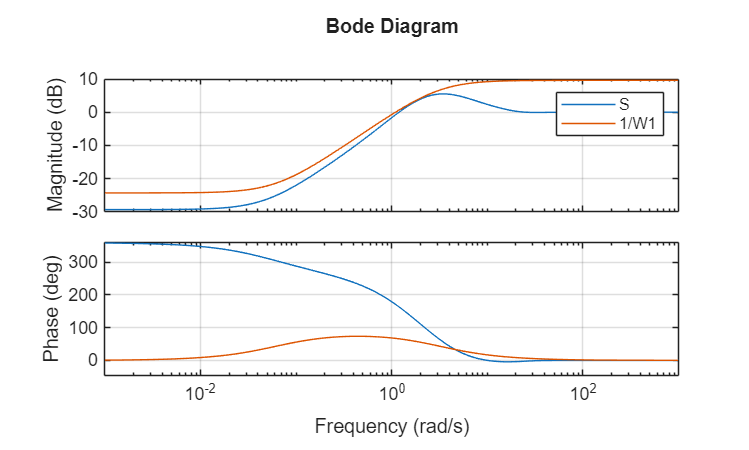


% Comparison between the augmented system transfer functions and the
% weighting functions
S  = 1/(1+K*sys_syn);
GS = sys_syn/(1+K*sys_syn);
KS = K/(1+K*sys_syn);
T  = K*sys_syn/(1+K*sys_syn);

figure
bode(S,1/sysW1)
legend('S','1/W1')
grid

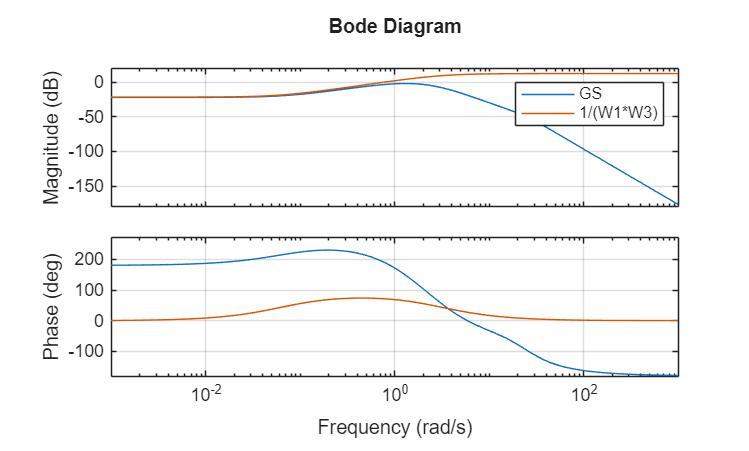


figure
bode(GS,1/(sysW1*sysW3))
legend('GS','1/(W1*W3)')
grid

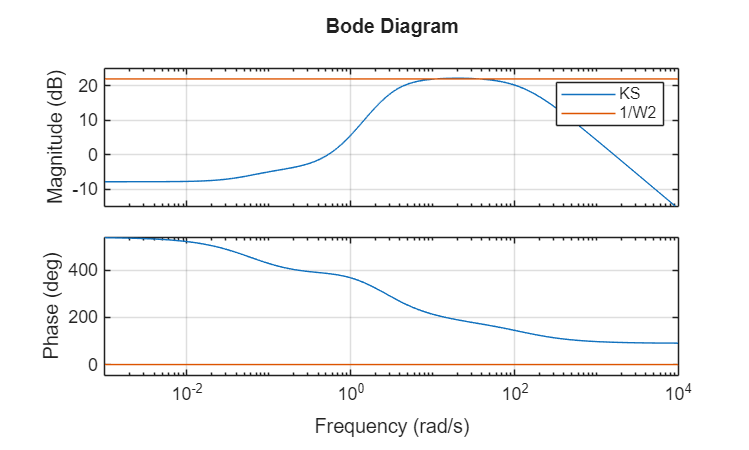


figure
bode(KS,1/sysW2)
legend('KS','1/W2')
grid

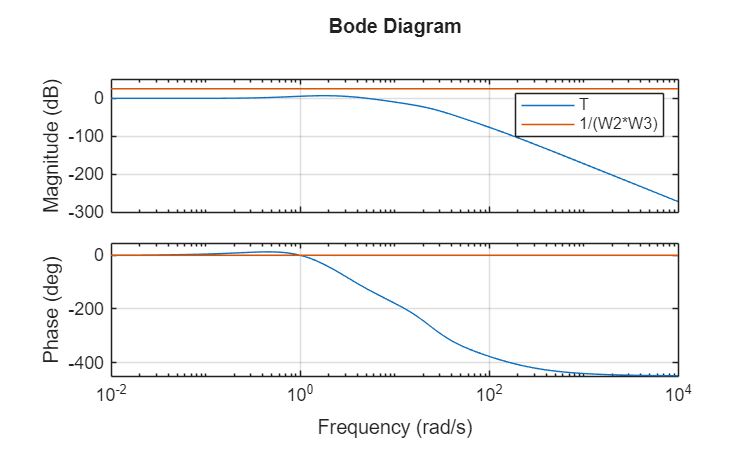


figure
bode(T,1/(sysW2*sysW3))
legend('T','1/(W2*W3)')
grid

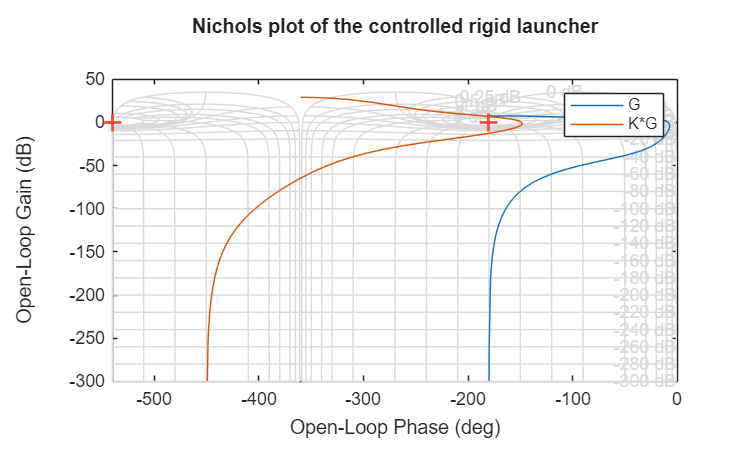


% Frequency domain assessment (rigid launcher)
figure
nichols(sys_syn,K*sys_syn)
legend('G','K*G')
grid
title('Nichols plot of the controlled rigid launcher')

allmargin(K*sys_syn)

ans = struct with fields:
     GainMargin: [0.4514 4.2585]
    GMFrequency: [0.9972 10.1151]
    PhaseMargin: 31.2671
    PMFrequency: 2.8631
    DelayMargin: 0.1906
    DMFrequency: 2.8631
         Stable: 1


% Time domain simulation (rigid launcher)

% case 1: zero guidance input, no wind, constant thrust deflection offset
% 0.1deg
t  = [0:0.1:100]';
nt = max(size(t));

thetac     = 0;
ventonoff = 0;
betafz    = 0.1*3.14/180;

[tt,x,y] = sim('rigid_launcher_CL',[0 max(t)]);

plot_rigid_launcher_simu


% case 2: zero guidance input, wind profile, no thrust deflection offset
t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 1/58;
ventonoff = 1;
betafz    = 0;

[tt,x,y] = sim('rigid_launcher_CL',[0 max(t)]);

plot_rigid_launcher_simu

% sensitivity analysis has to be completed
%

% Be carefull to reinitialze the weighting functions to their initial values before each analysis
k1 = 0.33;
a1 = 3.14;
b1 = 0.0628;
k2 = 0.08;
a2 = 22;
b2 = 22;
k3 = 0.7;
% Synthesize the results in a table


% 5.2.1 - Hinf rigid motion controller settings (Q18)
% ------------------------------------------------

% 5.2.2 - Hinf rigid motion controller settings (Q19)
% ------------------------------------------------


%---------------------------------------------------------------------------
% 	6 - Flexible launcher control
%---------------------------------------------------------------------------

% 6.1.2 - Frequency domain assessment model (flexible launcher)
% -----------------------------------------------------------
% Flexible launcher model for synthesis
% State vector    : x^T = (Theta',Theta,z',beta_R',beta_R,q',q)
% Input vector  : u^T = (beta_c)
% Output vector : y^T = (Thetam)

% Flexible launcher data
Ams = [0 0 0 0 Aq -2*xiq*omegaq -omegaq^2;
       0 0 0 0  0             1         0];

Bms = zeros(2,3);

As = [Ar zeros(5,2);
      Ams];

Bs = [ Br;
      Bms];

Cs = [eye(7,7);
      Calpha 0 0];

Ds = [zeros(7,3);
          Dalpha];

% Q20: build the linear model for time simulation (file "flexible_launcher_syn")
[aefbo,befbo,cefbo,defbo] = linmodv5('flexible_launcher_syn');
valefbo = eig(aefbo);

sys_ef = ss(aefbo,befbo,cefbo,defbo);
tf(sys_ef);


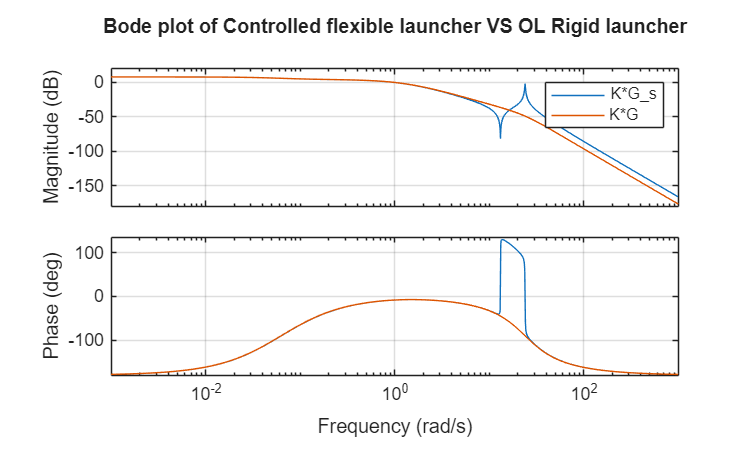


% 6.2 - Frequential domain assessment (flexible launcher)
% -----------------------------------------------
% Q21/22: Bode plot of the controlled flexible launcher
figure
bode(sys_ef,sys_syn);
legend('K*G_s','K*G')
grid
title('Bode plot of Controlled flexible launcher VS OL Rigid launcher')

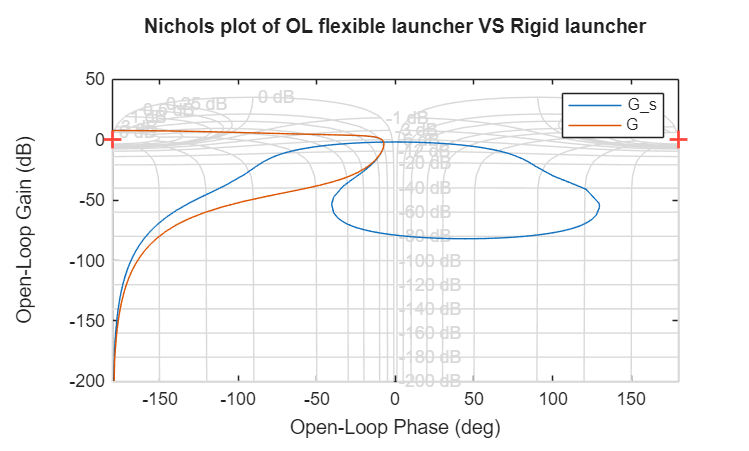


% Q21/22: Nichols plot of the controlled flexible launcher
figure

nichols(sys_ef,sys_syn);
legend('G_s','G')
grid
title('Nichols plot of OL flexible launcher VS Rigid launcher')

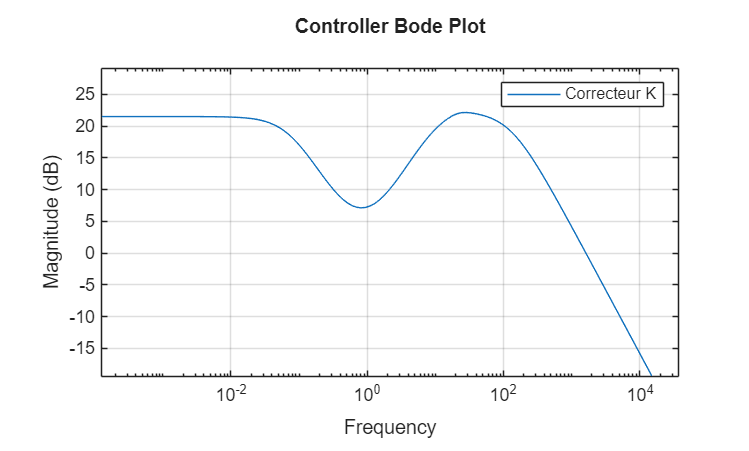

figure;
bodemag(K)
legend('Correcteur K')
title('Controller Bode Plot')
grid on 

[Zeros,Poles,gain] = zpkdata(sys_ef,'v')

Zeros =   -0.0249 +13.1101i
  -0.0249 -13.1101i
  -0.0787 + 0.0000i


Poles =   -1.3246 + 0.0000i
   1.2276 + 0.0000i
   0.0503 + 0.0000i
 -15.0570 +18.5606i
 -15.0570 -18.5606i
  -0.1194 +23.8797i
  -0.1194 -23.8797i


gain = -4.7332e+03

% Q22: poles of the closed-loop system
[Zeros,Poles,gain] = zpkdata(feedback(K,sys_ef),'v')

Zeros =   -0.1194 +23.8797i
  -0.1194 -23.8797i
  -0.5413 + 0.0000i
  -1.2674 + 0.0000i
  -0.0671 + 0.0000i
 -15.0570 +18.5606i
 -15.0570 -18.5606i
 -15.0570 +18.5606i
 -15.0570 -18.5606i
  -1.3246 + 0.0000i
   1.2276 + 0.0000i
   0.0503 + 0.0000i


Poles = 1.0e+02 *

  -1.2561 + 0.0000i
   0.0099 + 0.2404i
   0.0099 - 0.2404i
  -0.1649 + 0.1970i
  -0.1649 - 0.1970i
  -0.1506 + 0.1856i
  -0.1506 - 0.1856i
  -0.0234 + 0.0163i
  -0.0234 - 0.0163i
  -0.0145 + 0.0059i
  -0.0145 - 0.0059i
  -0.0007 + 0.0000i
  -0.0008 + 0.0000i


gain = -1.6383e+03

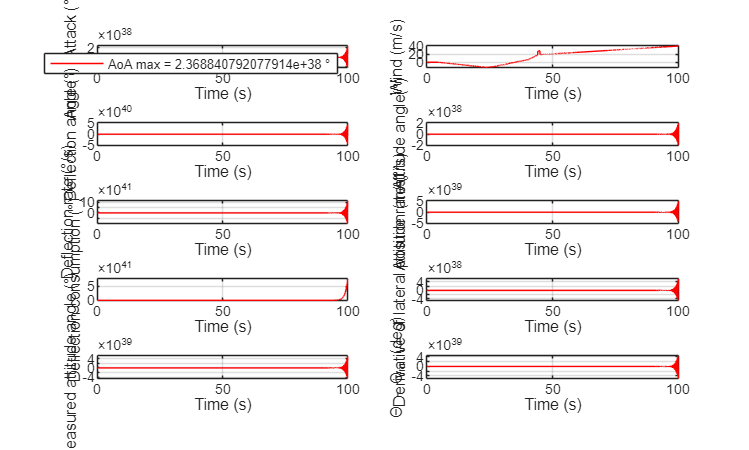



% 6.3 - Time domain simulation (flexible launcher)
% -----------------------------------------------
% Input = deflection step (magnitude = 1° during 1s)  
% same conditions as 2.1 for rigid launcher
% flexible_launcher_CL.mdl is given

% Q23: case 2: zero guidance input, wind profile, no thrust deflection offset
t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 0;
ventonoff = 1;
betafz    = 0;

[tt,x,y] = sim('flexible_launcher_CL',[0 max(t)]);

plot_flexible_launcher_simu

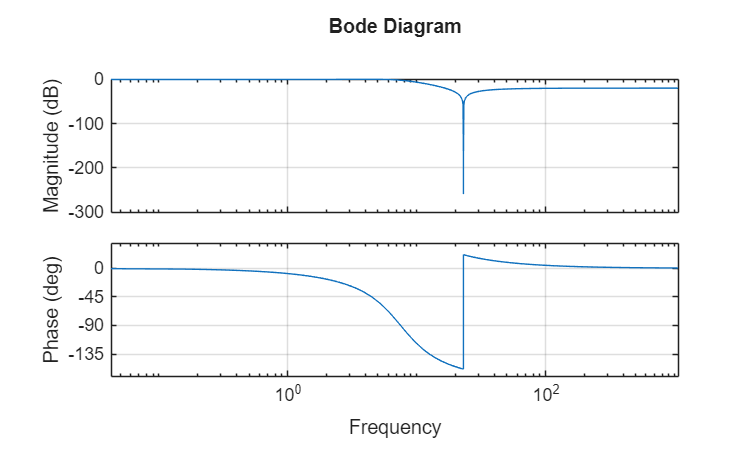


% 6.4 - Flexible motion filter settings
% -----------------------------------------------
% 6.4.1 - Filtering needs

% Q24: Lowpass filter of order 2 on the commanded deflection
[filtnum1,filtden1] = ellip(2,0.5,20,6,'s');
filt1 = tf(filtnum1,filtden1);
figure
bode(filt1)
grid on

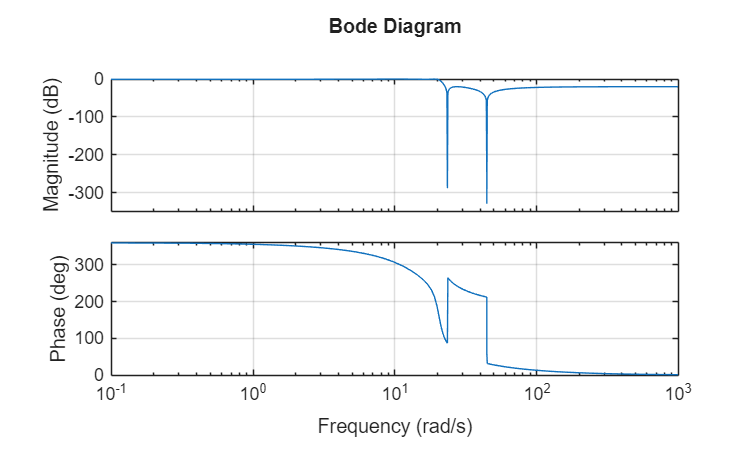


% Q24: Lowpass filter of order 4 on the commanded deflection
[filtnum2,filtden2] = ellip(4,0.5,20,20,'s');
filt2 = tf(filtnum2,filtden2);
figure
bode(filt2)
grid on

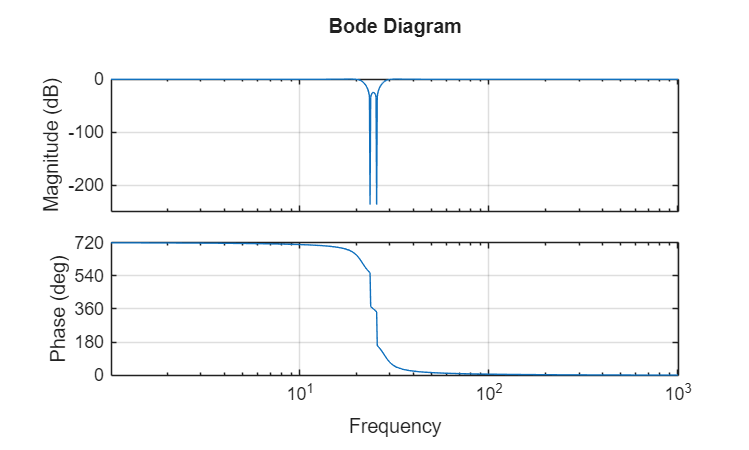


% Q24: Band stop filter of order 4 on the commanded deflection
[filtnum3,filtden3] = ellip(2,0.5,25,[20 30],'stop','s');
filt3 = tf(filtnum3,filtden3);
figure
bode(filt3)
grid on

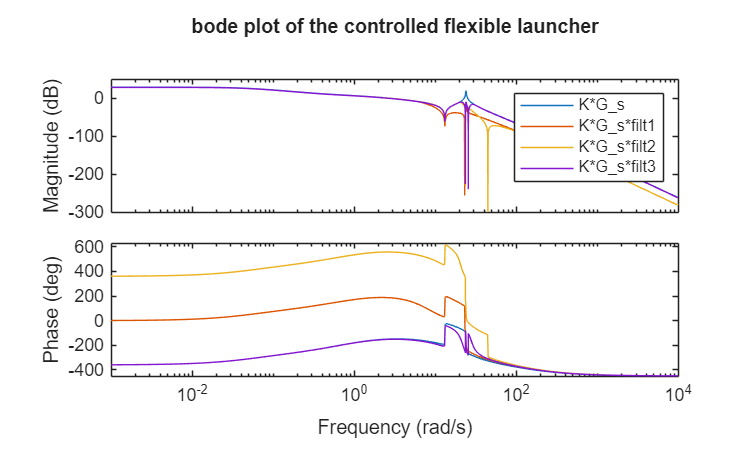

% to be completed ...
figure 
grid on
bode(K*sys_ef,K*sys_ef*filt1,K*sys_ef*filt2,K*sys_ef*filt3)
legend('K*G_s','K*G_s*filt1','K*G_s*filt2','K*G_s*filt3')
title('bode plot of the controlled flexible launcher')

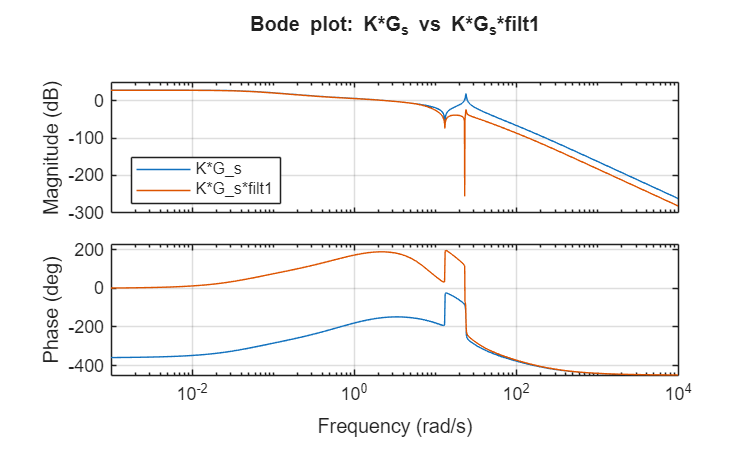

figure
bode(K*sys_ef, K*sys_ef*filt1)
grid on
legend('K*G_s','K*G_s*filt1','Location','best')
title('Bode plot: K*G_s vs K*G_s*filt1')

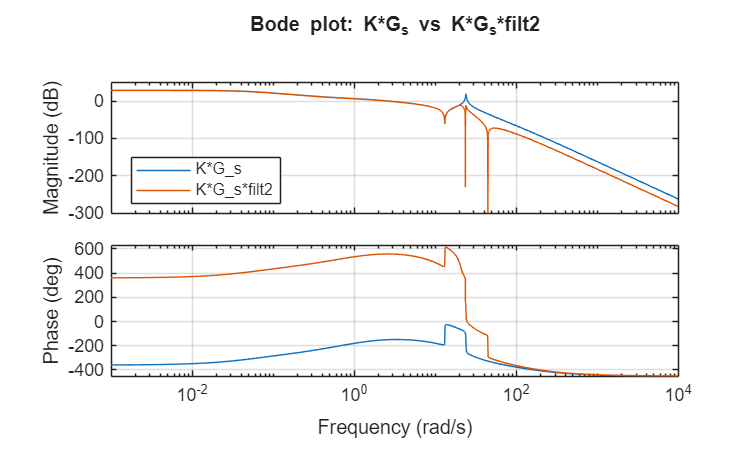


figure
bode(K*sys_ef, K*sys_ef*filt2)
grid on
legend('K*G_s','K*G_s*filt2','Location','best')
title('Bode plot: K*G_s vs K*G_s*filt2')

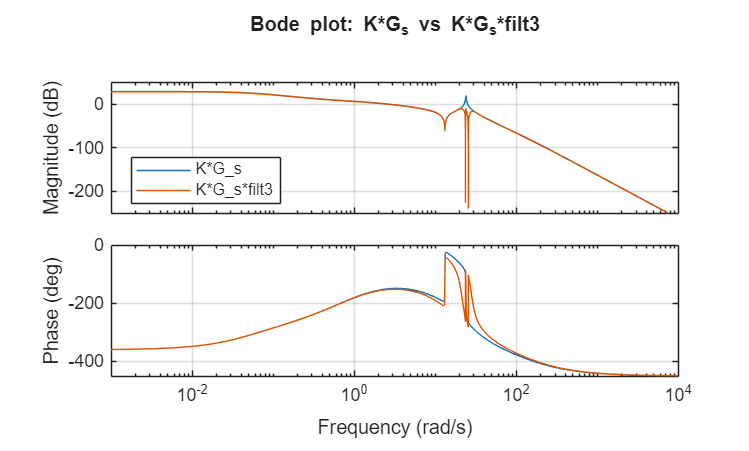


figure
bode(K*sys_ef, K*sys_ef*filt3)
grid on
legend('K*G_s','K*G_s*filt3','Location','best')
title('Bode plot: K*G_s vs K*G_s*filt3')

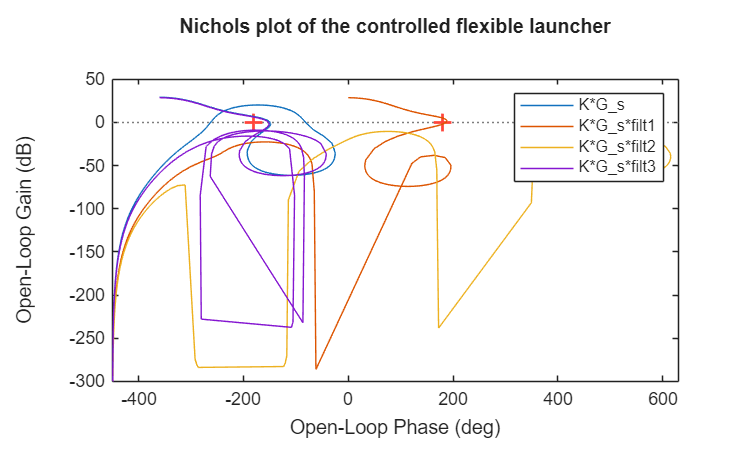


% 6.4.2 - Frequency domain assessment
% Q25: Nichols plot of the controlled flexible launcher
figure 
grid on
nichols(K*sys_ef,K*sys_ef*filt1,K*sys_ef*filt2,K*sys_ef*filt3)
legend('K*G_s','K*G_s*filt1','K*G_s*filt2','K*G_s*filt3')
title('Nichols plot of the controlled flexible launcher')

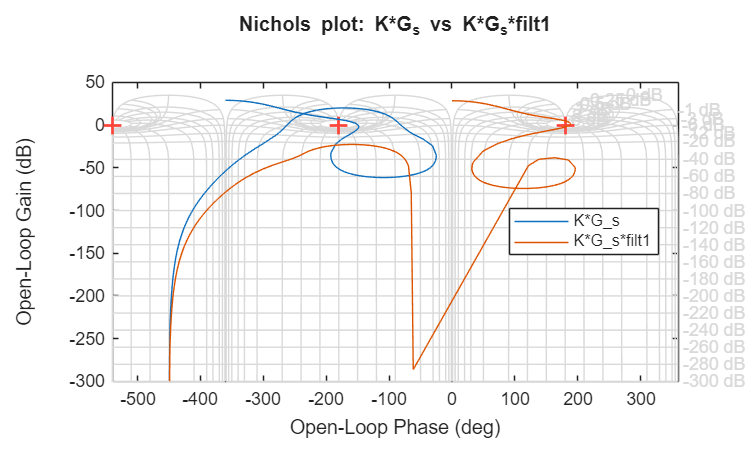

figure
nichols(K*sys_ef, K*sys_ef*filt1)
grid on
legend('K*G_s','K*G_s*filt1','Location','best')
title('Nichols plot: K*G_s vs K*G_s*filt1')

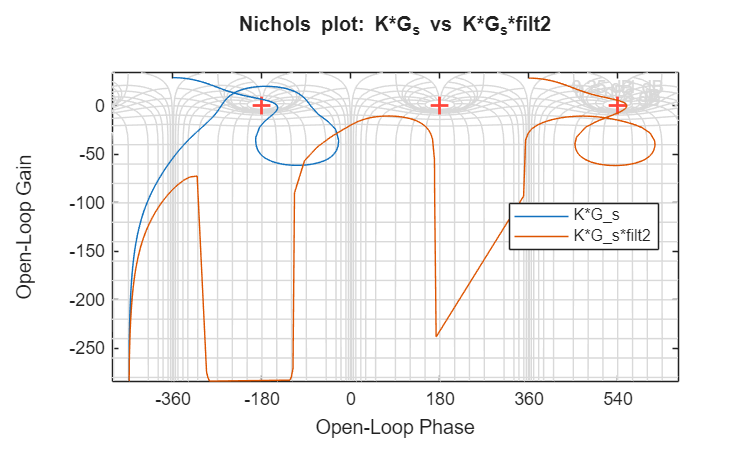


figure
nichols(K*sys_ef, K*sys_ef*filt2)
grid on
legend('K*G_s','K*G_s*filt2','Location','best')
title('Nichols plot: K*G_s vs K*G_s*filt2')

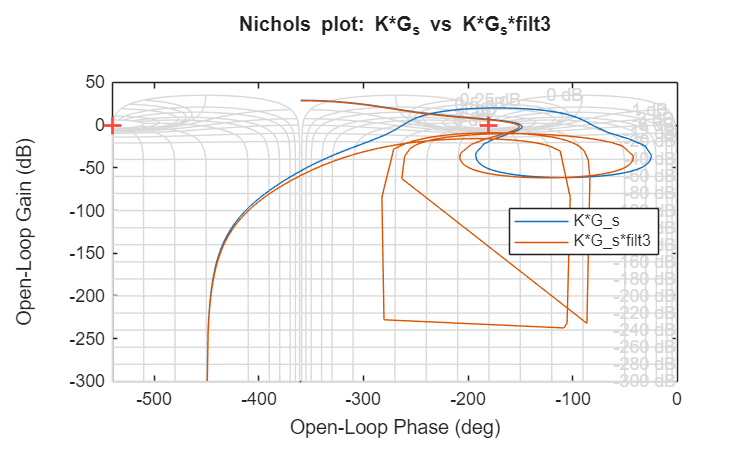


figure
nichols(K*sys_ef, K*sys_ef*filt3)
grid on
legend('K*G_s','K*G_s*filt3','Location','best')
title('Nichols plot: K*G_s vs K*G_s*filt3')

allmargin(K*sys_ef*filt1)

ans = struct with fields:
     GainMargin: [0.5598 1.2661 2.0221e+03 93.9854 14.3435]
    GMFrequency: [1.2709 3.4238 13.1686 15.4921 23.9426]
    PhaseMargin: 6.8437
    PMFrequency: 2.6823
    DelayMargin: 0.0445
    DMFrequency: 2.6823
         Stable: 1


allmargin(K*sys_ef*filt2)

ans = struct with fields:
     GainMargin: [0.5175 2.2992 1.1810e+03 5.4108 3.1503e+03 5.8353e+07]
    GMFrequency: [1.1147 5.4383 13.1126 18.1750 23.4873 44.5333]
    PhaseMargin: 18.4150
    PMFrequency: 2.6073
    DelayMargin: 0.1233
    DMFrequency: 2.6073
         Stable: 1


allmargin(K*sys_ef*filt3)

ans = struct with fields:
     GainMargin: [0.4892 5.6333 687.6282 3.2812 8.9786e+04 2.7976 2.2079e+05 6.3265]
    GMFrequency: [1.0172 8.6700 13.0740 21.3806 23.5323 23.9158 25.4968 28.3427]
    PhaseMargin: 27.9897
    PMFrequency: 2.5887
    DelayMargin: 0.1887
    DMFrequency: 2.5887
         Stable: 1


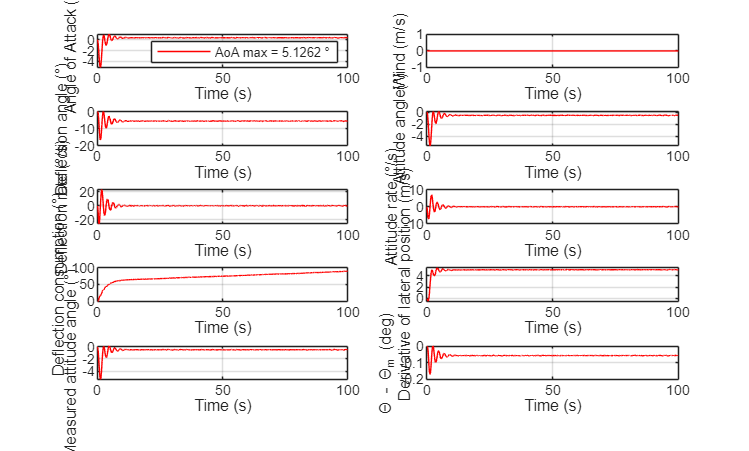

% 6.4.3 - Time domain simulation
% use flexible_launcher_CL_filter.mdl
% Q26: case a: zero guidance input, no wind, constant thrust deflection offset
% 0.1deg

% Q26: case b: zero guidance input, wind profile, no thrust deflection offset

% to be completed 
...
[afilt,bfilt,cfilt,dfilt] = ssdata(filt1);
[asbff3,bsbff3,csbff3,dsbff3] = linmodv5('flexible_launcher_CL_filter');
valsbff3 = eig(asbff3);


t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 0;
ventonoff = 0;
betafz    = 0.1;

[tt,x,y] = sim('flexible_launcher_CL_filter',[0 max(t)]);

plot_flexible_launcher_simu

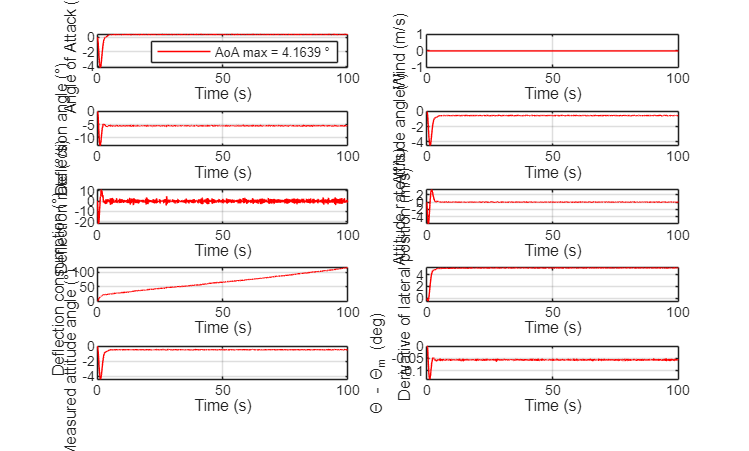

[afilt,bfilt,cfilt,dfilt] = ssdata(filt2);
[asbff3,bsbff3,csbff3,dsbff3] = linmodv5('flexible_launcher_CL_filter');
valsbff3 = eig(asbff3);


t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 0;
ventonoff = 0;
betafz    = 0.1;

[tt,x,y] = sim('flexible_launcher_CL_filter',[0 max(t)]);

plot_flexible_launcher_simu

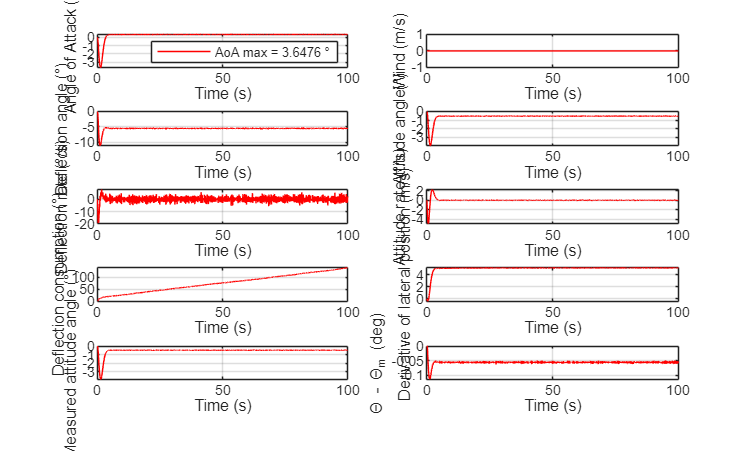

% to be completed ...
...

[afilt,bfilt,cfilt,dfilt] = ssdata(filt3);
[asbff3,bsbff3,csbff3,dsbff3] = linmodv5('flexible_launcher_CL_filter');
valsbff3 = eig(asbff3);


t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 0;
ventonoff = 0;
betafz    = 0.1;

[tt,x,y] = sim('flexible_launcher_CL_filter',[0 max(t)]);

plot_flexible_launcher_simu

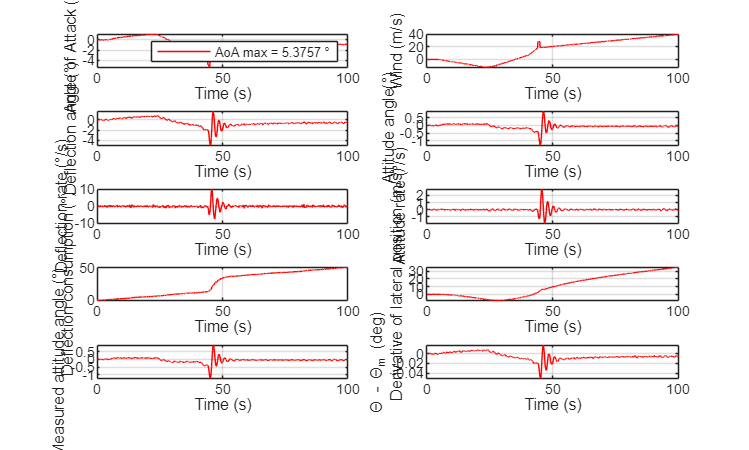

[afilt,bfilt,cfilt,dfilt] = ssdata(filt1);
[asbff3,bsbff3,csbff3,dsbff3] = linmodv5('flexible_launcher_CL_filter');
valsbff3 = eig(asbff3);


t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 0;
ventonoff = 1;
betafz    = 0;

[tt,x,y] = sim('flexible_launcher_CL_filter',[0 max(t)]);

plot_flexible_launcher_simu

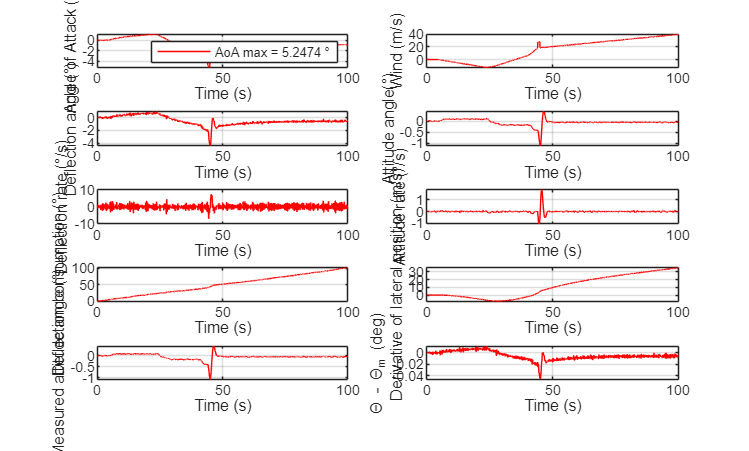

[afilt,bfilt,cfilt,dfilt] = ssdata(filt2);
[asbff3,bsbff3,csbff3,dsbff3] = linmodv5('flexible_launcher_CL_filter');
valsbff3 = eig(asbff3);


t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 0;
ventonoff = 1;
betafz    = 0;

[tt,x,y] = sim('flexible_launcher_CL_filter',[0 max(t)]);

plot_flexible_launcher_simu

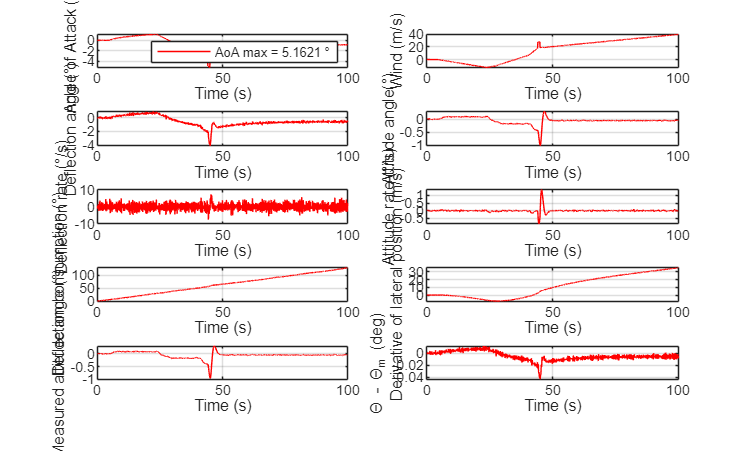

% to be completed ...
...

[afilt,bfilt,cfilt,dfilt] = ssdata(filt3);
[asbff3,bsbff3,csbff3,dsbff3] = linmodv5('flexible_launcher_CL_filter');
valsbff3 = eig(asbff3);


t  = [0:0.1:100]';
nt = max(size(t));

thetac    = 0;
ventonoff = 1;
betafz    = 0;

[tt,x,y] = sim('flexible_launcher_CL_filter',[0 max(t)]);

plot_flexible_launcher_simu